# Hoja 2B

Ejercicio 1

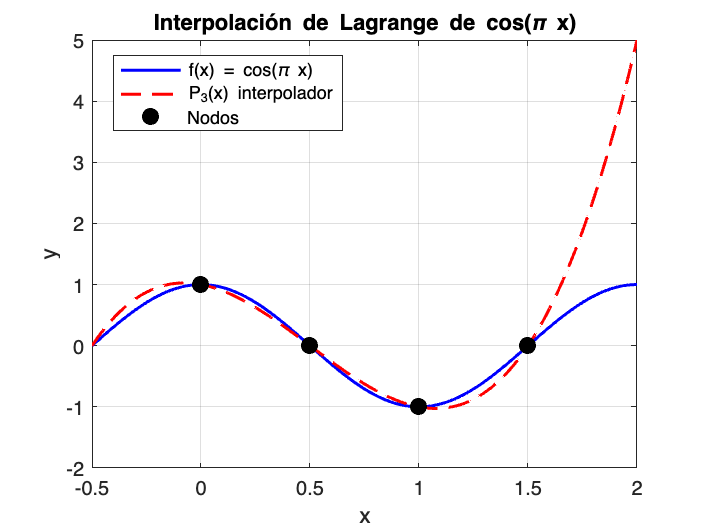

% Datos
x_nodos = [0, 0.5, 1, 1.5];
y_nodos = cos(pi * x_nodos);

% Polinomio P3(x)
P3 = @(x) (8/3)*x.^3 - 4*x.^2 - (2/3)*x + 1;

% Puntos para graficar
x_vals = linspace(-0.5, 2, 400);
f_vals = cos(pi * x_vals);
p_vals = P3(x_vals);

% Gráfica
figure;
plot(x_vals, f_vals, 'b-', 'LineWidth', 1.5); hold on;
plot(x_vals, p_vals, 'r--', 'LineWidth', 1.5);
plot(x_nodos, y_nodos, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
grid on; xlabel('x'); ylabel('y');
legend('f(x) = cos(\pi x)', 'P_3(x) interpolador', 'Nodos', 'Location', 'Best');
title('Interpolación de Lagrange de cos(\pi x)');